clear all;

path_opt_table= readtable('traj_opt.csv');

s_opt_table= readtable('length_opt.csv');

    
% london_outer_table=readtable('london_outer.csv');
% london_inner_table=readtable('london_inner.csv');

ref_xy= [path_opt_table.x_Traj_x, path_opt_table.traj_y];
s_opt= s_opt_table.x_S_opt;

dt= 0.05; % stepwise
t_list= (0:dt:1)'; % total time
u_steer_dis= deg2rad((-15:1.5:15)');

state_passed= [];
path_index_list=[];
d_paths_max_list=[];
index_list=[];

v_last_iter=0;
state0= [ref_xy(1,1); ref_xy(1,2); 0; 0.01];

for iter=1:1
    [state, u] = StateUpdate_dt(state0, u_steer_dis, t_list, dt, v_last_iter);
    
    %%% find the end points of generated paths %%%
    paths_EndPoints=[];
    path_length=[];
    path_devi=[];
    
    for j= 1:length(t_list):length(state)
        path_length_tmp= 0;
        check=[];
        paths_points=[];
        path_devi_tmp=[];
        
        %paths_EndPoints= [paths_EndPoints; [state(2, j+length(t_list)-1), state(3, j+length(t_list)-1)]];
        paths_points= [state(2,j:j+length(t_list)-1)',state(3,j:j+length(t_list)-1)'];
        
        %%% compute the length and deviate of each path %%%
        for k= 1:length(paths_points)-1
            path_length_points= norm([paths_points(k+1,1)-paths_points(k,1), paths_points(k+1,2)-paths_points(k,2)], 2);
            path_length_tmp= path_length_tmp+ path_length_points;
            path_devi_tmp= [path_devi_tmp, (paths_points(k+1,2)-paths_points(k,2))/(paths_points(k+1,1)-paths_points(k,1))];
        end
        
        path_devi= [path_devi; path_devi_tmp];
        path_length= [path_length; path_length_tmp];
    end
    
    
    %%% find the cloest point index on the ref path %%%
    s_criter= max(path_length);
    s_ref=0;
    index=1;
    while(s_ref< s_criter)
        s_ref= s_ref+ s_opt(index);
        index= index+1;
    end
    
    %%% calculate the deviate of ref path %%
    ref_devi=[];
    for k= 1:index-1
        ref_devi=[ref_devi; (ref_xy(index+1,2)- ref_xy(index,2))/(ref_xy(index+1,1)- ref_xy(index,1))];
    end
    
    %%% update variables for next iteration
    
end

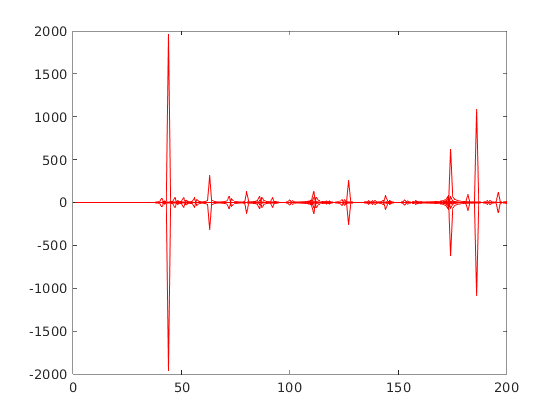

Index in position 1 exceeds array bounds (must not exceed 21).

close all;

for i= 1:length(path_devi)
    plot(path_devi(i,:), 'color', 'red');
    hold on;
end


plot(ref_devi, 'color', 'blue');
hold off